# Semestralka B2M31AEDA

## Nahrání dat

T = readtable('Zadani_I.xlsx','ReadVariableNames',true);

T = T(:, {'Subject','Gender','Age','RFA_1','stdPWR_2','RLR','RFA','DDKI','DPI','LRE','stdPWR_1','stdF0_1','stdF0_2'});

**Logistická regrese**

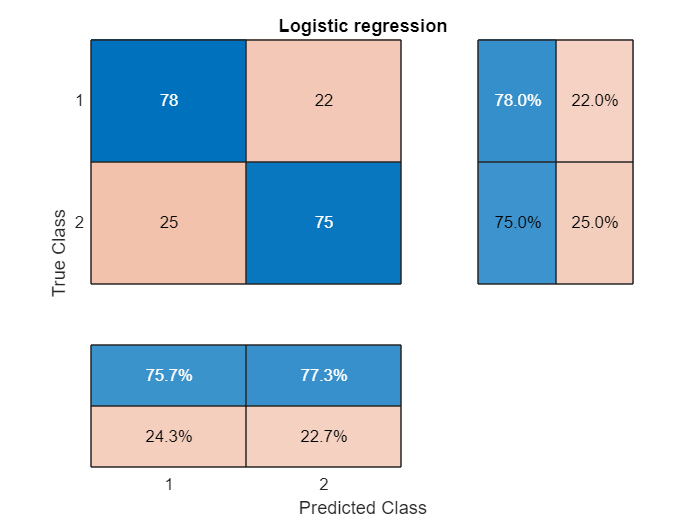

X = table2array(T(:, {'Age','RFA_1','stdPWR_2','RLR','RFA','DDKI','DPI','LRE','stdPWR_1','stdF0_1','stdF0_2'}));
y = double(strcmp(T.Subject, 'PD'));

k = 5;
cv = cvpartition(length(y), 'KFold', k);

threshold = 0.5;

cm = zeros(2, 2);

for fold = 1:k

    trainIdx = training(cv, fold);
    X_train = X(trainIdx, :);
    y_train = y(trainIdx);
    
    testIdx = test(cv, fold);
    X_test = X(testIdx, :);
    y_test = y(testIdx);
    
    logisticModel = fitglm(X_train, y_train, 'Distribution', 'binomial', 'Link', 'logit');
    
    predictedProbabilities = predict(logisticModel, X_test);
    
    predictedLabels = predictedProbabilities >= threshold;

    cm = cm + confusionmat(y_test, double(predictedLabels));
end

confusionchart(cm, 'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized', 'Title', 'Logistic regression');


accuracy = sum(diag(cm)) / sum(cm(:));
precision = cm(2, 2) / sum(cm(:, 2));
recall = cm(2, 2) / sum(cm(2, :));
f1Score = 2 * (precision * recall) / (precision + recall);

disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.765


disp(['Precision: ', num2str(precision)]);

Precision: 0.7732


disp(['Recall: ', num2str(recall)]);

Recall: 0.75


disp(['F1-Score: ', num2str(f1Score)]);

F1-Score: 0.76142


**Support Vector Machine **s lineárním jádrem

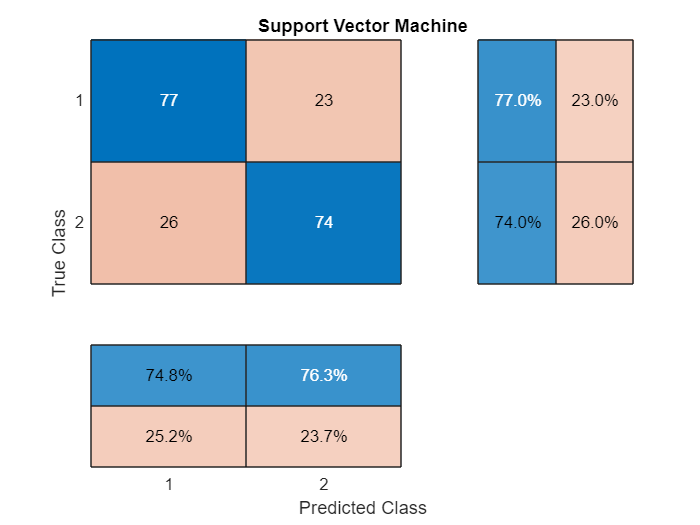

X = table2array(T(:, {'Age','RFA_1','stdPWR_2','RLR','RFA','DDKI','DPI','LRE','stdPWR_1','stdF0_1','stdF0_2'}));
y = double(strcmp(T.Subject, 'PD'));

k = 5;
cv = cvpartition(length(y), 'KFold', k);

cm = zeros(2, 2);

for fold = 1:k

    trainIdx = training(cv, fold);
    X_train = X(trainIdx, :);
    y_train = y(trainIdx);
    
    testIdx = test(cv, fold);
    X_test = X(testIdx, :);
    y_test = y(testIdx);
    
    svmModel = fitcsvm(X_train, y_train, 'Standardize', true, 'KernelFunction', 'linear');
    
    predictedLabels = predict(svmModel, X_test);
    
    cm = cm + confusionmat(y_test, predictedLabels);
end

confusionchart(cm, 'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized', 'Title', 'Support Vector Machine');


accuracy = sum(diag(cm)) / sum(cm(:));
precision = cm(2, 2) / sum(cm(:, 2));
recall = cm(2, 2) / sum(cm(2, :));
f1Score = 2 * (precision * recall) / (precision + recall);

disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.755


disp(['Precision: ', num2str(precision)]);

Precision: 0.76289


disp(['Recall: ', num2str(recall)]);

Recall: 0.74


disp(['F1-Score: ', num2str(f1Score)]);

F1-Score: 0.75127
